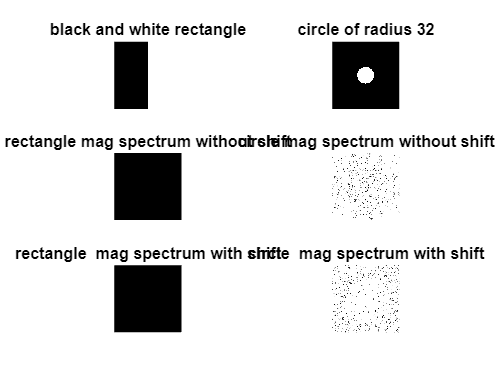

x=zeros(255,255);
for i=1:255
    for j=1:127
       x(i,j)=1;
    end
end
fft_x=fft2(x);
fft_shift_x=fftshift(fft_x);
abs_fft_shift_x=abs(fft_shift_x);
abs_fft_x=abs(fft_x);
%%
r=32;x_c=0;y_c=0;
[y,x]=ndgrid(-127:128,-127:128);
y= (x-x_c).^2+(y-y_c).^2 <= r^2;

fft_y=fft2(y);
fft_shift_y=fftshift(fft_y);
abs_fft_shift_y=abs(fft_shift_y);
abs_fft_y=abs(fft_y);
subplot(3,2,1);imshow(x);title('black and white rectangle');
subplot(3,2,2);imshow(y);title('circle of radius 32');
subplot(3,2,3);imshow(abs_fft_x);title('rectangle mag spectrum without shift');
subplot(3,2,4);imshow(abs_fft_y);title('circle mag spectrum without shift');
subplot(3,2,5);imshow(abs_fft_shift_x);title('rectangle  mag spectrum with shift');
subplot(3,2,6);imshow(abs_fft_shift_y);title('circle  mag spectrum with shift');